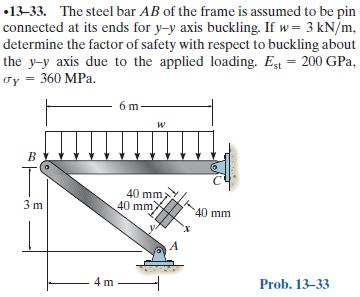

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-33P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-33P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

theta = atand(sym(3/4))*u.deg;
wo = 3*u.kN/u.m;
Pab = sym('Pab');
Rb(Pab) = Pab*sin(theta);

# section properties

Eab = 200*u.GPa;
Iab = sym(80)*sym(40)^3/12*u.mm^4;
Lab = 5*u.m;

# beam

b = beam;
b = b.add('reaction', 'force', Rb, 0);
b = b.add('reaction', 'force', 'Rc', 6*u.m);
b = b.add('distributed', 'force', -wo, [0 6]*u.m);
b.L = 6*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \frac{x\,\left(x-6\,m\right)\,\left(-x^{2}+6\,x\,m+36\,m^{2}\right)}{8\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m}$$

dy

$$dy(x) = \frac{\left(x-3\,m\right)\,\left(-x^{2}+6\,x\,m+18\,m^{2}\right)}{2\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m}$$

m

$$m(x) = -\frac{3\,x\,\left(x-6\,m\right)}{2}\,\frac{\mathrm{kN}}{m}$$

v

$$v(x) = -3\,\left(x-3\,m\right)\,\frac{\mathrm{kN}}{m}$$

w

$$w(x) = -3\,\frac{\mathrm{kN}}{m}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Pab} & 15\,\mathrm{kN}\\ \mathrm{Rc} & 9\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

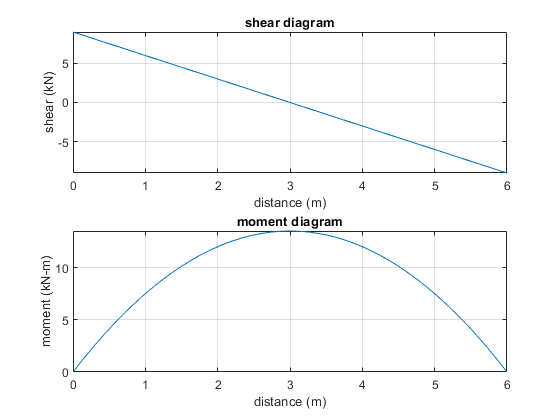

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# factor of safety against buckling

sigma_yield = 360*u.MPa;
Pcr = rewrite(sympi^2*Eab*Iab/Lab^2, u.kN);
Pcr_vpa = vpa(Pcr, 4) %#ok

$$Pcr\_vpa = 33.69\,\mathrm{kN}$$

FS = Pcr/rs.Pab;
FS_vpa = vpa(FS, 3) %#ok

$$FS\_vpa = 2.25$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear Pcr_vpa FS_vpa;